# Statistical Behaviour of Cryptocurrencies

Giacomo Marciani

Department of Civil and Computer Engineering

University of Rome Tor Vergata

[gmarciani@acm.org](mailto:gmarciani@acm.org)

## `Abstract`

`This script visualizes a comparative study about the statistical behaviour of cryptocurrencies. The dataset can be fetched both from Cryptocompare[1] and CoinAPI[2], through their public REST API[3,4].`

`The script allows to compare an arbitrary number of cryptocurrencies and it is initialized with the following ones:`

- `BTC: Bitcoin[5];`

- `ETH: Ethereum[6];`

`This work is inteded as a final test for the course in Advanced Statistics[7,8,9].`

## `Introduction`

`First of all, let us declare the parameters for the study.`

currencies = ["BTC", "ETH"];
change = "EUR";
startTime = datetime("01-Sep-2015");
endTime = datetime("11-Mar-2018");
period = caldays(10);
dataSource.name = "cryptocompare";
%dataSource.name = "coinapi";
%dataSource.apiKey = "B2EFCBEF-BB91-441E-8491-C06F880EC5EC"; % required by CoinAPI

`You can customize the study by editing the above variables:`

- `currencies``: an array of cryptocurrencies. Possible values are official exchange codes, e.g. BTC (Bitcoin), ETH (Ethereum), XRP (Ripple).`

- `change``: a real currency. Possible values are official money codes, e.g. EUR (Euro), USD (American Dollars), GBP (UK Pound).`

- `startTime``: a DateTime specifing the time lower bound for the historical data, e.g. datetime("01-Sep-2015") or datetime("now") - years(3).`

- `endTime``: a DateTime specifing the time upper bound for the historical data, e.g. datetime("01-Mar-2018") or datetime("now").`

- `period``: a CalendarDuration specifing the sampling period within the interval [startTime,endTime], e.g. caldays(10) or calmonths(1).`

- `dataSource.name``: a string indicating the data source from which data has to be fetched. Possible values are "cryptocompare" and "coinapi". Notice that Cryptocompare[1] provides datasets with a few measures spanning a very large period of time and imposes a limit of 6000 requests/hour where each request returns a measure for a given timestamp; CoinAPI[2] provides datasets spanning a less time period with a lot of measures and imposes a limit of 100 requests/day where each request can return timestamped measures for a given period and a samling pace.`

- `datasource.apiKey``: a string containing the API key to authorize the access to the data source. This is required by CoinAPI only.`

`Please, notice that if you modify the above variables, you should also modify the variables ``dists`` in Distribution Analysis and ``fits`` in Forecasting. `

## `Setup`

`First, let us acquire the dataset and setup the required support variables:`

n = length(currencies);
data = repmat(struct('name', [], 'T', [], 'w', []), n, 1);
for i = 1:n
    data(i).name = currencies(i);
    data(i).T = fetchData(dataSource, data(i).name, change, startTime, endTime, period);
end

`Notice that this is a separate section, so data fetching and data evaluation in the next section have been decoupled.`

## `Annual Trend`

`Let us now visualize the annual trend of the currencies value.`

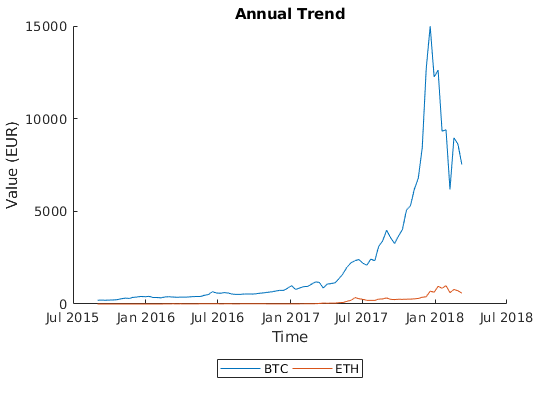

hold on

for i = 1:n
    plot(data(i).T.Time, data(i).T.Value, 'DisplayName', data(i).name);
end

hold off

title('Annual Trend');
xlabel('Time');
ylabel(sprintf('Value (%s)', change));
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');


figure;

## `W-Measure`

`Let us now consider the following measure`


$$w_{i}:=\frac{x_{i}-x_{i-1}}{x_{i-1}}$$


`where `$x_{i}$` is the value of the considered indicator at time `$i$`.`

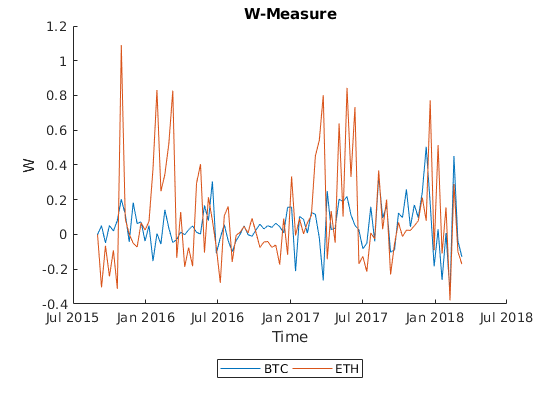

hold on

for i = 1:n
    data(i).w = getW(data(i).T.Value);
    plot(data(i).T.Time, data(i).w, 'DisplayName', data(i).name);
end

hold off

title('W-Measure');
xlabel('Time');
ylabel('W');
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');


figure;

## `Distribution Analysis`

`Let us now study the probability distribution function of the W-measure for the indicators. Please, notice that the variable ``dists`` should be modified accordingly to the result reported by the Distribution Fitter.`

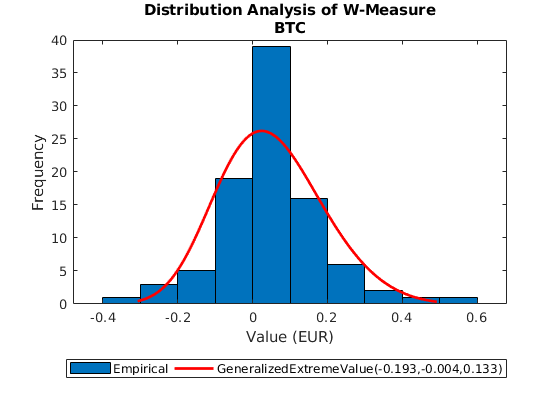

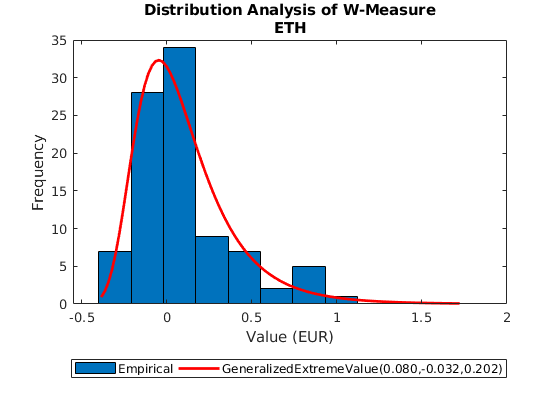

dists = ["GeneralizedExtremeValue", "GeneralizedExtremeValue"];

for i = 1:n
    bins = size(histcounts(data(i).w), 2);
    dparams = fitdist(data(i).w, char(dists(i)));

    histfit(data(i).w, bins, char(dists(i)));

    title({'Distribution Analysis of W-Measure', data(i).name});
    xlabel(sprintf('Value (%s)', change));
    ylabel('Frequency');
    legend('Empirical', sprintf("%s(%.3f,%.3f,%.3f)", dists(i), dparams.k, dparams.mu, dparams.sigma), 'Location', 'southoutside', 'Orientation', 'horizontal');
    figure;
end

## `Correlation Analysis`

`Let us now consider the correlation between the cryptocurrencies and their trends.`

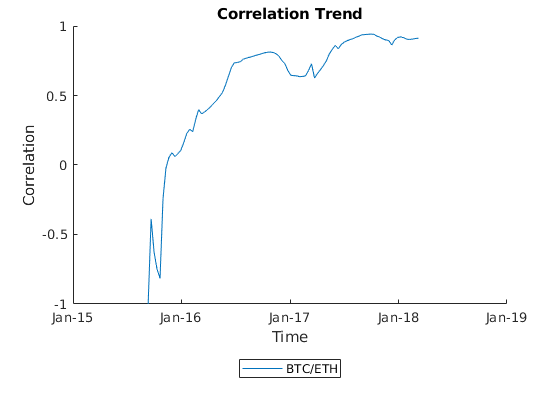

npairs = nchoosek(n,2);
corrData = repmat(struct('name1', [], 'name2', [], 'correlation', []), npairs, 1);
finalCorrelation = cell(npairs, 3);
pairIdx = 1;
for i = 1:n
    for j = (i+1):n
        mnTime = max(dateshift(data(i).T.Time(1), 'start', 'day'), dateshift(data(j).T.Time(1), 'start', 'day'));
        mxTime = min(dateshift(data(i).T.Time(end), 'start', 'day'), dateshift(data(j).T.Time(end), 'start', 'day'));
        intervalTime = mnTime+period:period:mxTime;
        rows = cell(length(intervalTime), 2);
        rowIdx = 1;
        for t = intervalTime
            vlsi = data(i).T(dateshift(data(i).T.Time, 'start', 'day') >= mnTime & dateshift(data(i).T.Time, 'start', 'day') <= t,:).Value;
            vlsj = data(j).T(dateshift(data(j).T.Time, 'start', 'day') >= mnTime & dateshift(data(j).T.Time, 'start', 'day') <= t,:).Value;
            
            try
                corrMatrix = corrcoef(vlsi, vlsj);
            catch exception
                error("Correlation Analysis cannot be done due to data mismatch near line %d. " + ...
                    "This error is raised by function corrcoef when the datasource does not provide the same data sampling for the selected cryptocurrencies. " + ...
                    "Original error message from corrcoef: %s", exception.stack(1).line, exception.message)
            end            
            
            rows(rowIdx,:) = {t, corrMatrix(1,2)};
            rowIdx = rowIdx + 1;
        end
        corrData(pairIdx).name1 = data(i).name;
        corrData(pairIdx).name2 = data(j).name;
        corrData(pairIdx).correlation = cell2table(rows, 'VariableNames', {'Time','Value'});
        finalCorrelation(pairIdx,:) = {data(i).name, data(j).name, corrMatrix(1,2)};
        pairIdx = pairIdx +1;
    end
end

hold on

for p = 1:npairs
    plot(corrData(p).correlation.Time, corrData(p).correlation.Value, 'DisplayName', sprintf("%s/%s", corrData(p).name1, corrData(p).name2));
end

hold off

title('Correlation Trend');
xlabel('Time');
ylabel('Correlation');
legend('show', 'Location', 'southoutside', 'Orientation', 'horizontal');
datetick('x', 'mmm-yy');

figure;

corrTable = cell2table(finalCorrelation, 'VariableNames', {'Currency1','Currency2','Correlation'});
corrTable = sortrows(corrTable, {'Correlation'});
disp(corrTable);

    Currency1    Currency2    Correlation
    _________    _________    ___________

    "BTC"        "ETH"        0.91229    



## `Forecasting`

`Let us now forecast the trend of the indicators by curve fitting. Please, notice that:`

- `fits`` should be modified accordingly to the result reported by the Curve Fitter;.`

- `futureTime`` should be modified accordingly to the desired future projection;`

- `futurePeriod`` should be modified accordingly to the desired forecasting sampling.`

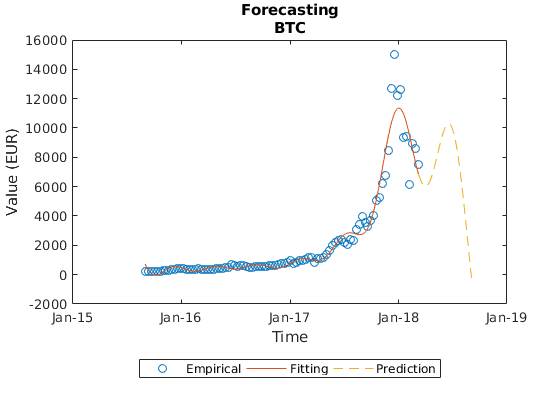

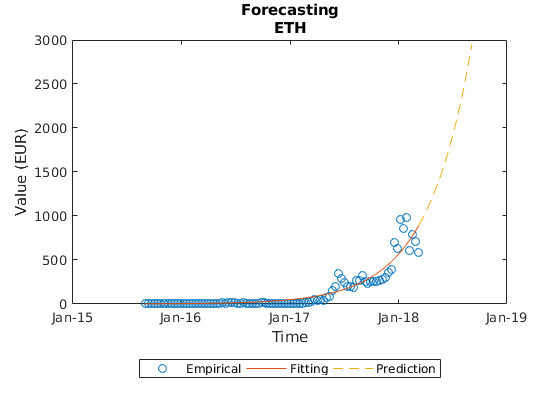

fits = ["sin7", "exp1"];
fitopts = [fitoptions('sin7', 'Normalize', 'on'),...
    fitoptions('exp1', 'Normalize', 'on')];
futureTime = endTime + calmonths(6);

for i = 1:n
    mnTime = min(data(i).T.Time);
    mxTime = max(data(i).T.Time);
    ts = datenum(data(i).T.Time);
    values = data(i).T.Value;
    
    fittingInterval = datenum(mnTime:mxTime);
    fitting = fit(ts, values, char(fits(i)), fitopts(i));
    fittingValues = fitting(fittingInterval);
    
    predictionInterval = datenum(mxTime:period:futureTime);
    predictionValues = fitting(predictionInterval);
    
    plot(ts, values, 'o');
    
    hold on
    plot(fittingInterval, fittingValues, '-');
    plot(predictionInterval, predictionValues, '--');
    hold off
    
    title({'Forecasting', data(i).name});
    xlabel('Time');
    ylabel(sprintf('Value (%s)', change));
    legend('Empirical', 'Fitting', 'Prediction', 'Location', 'southoutside', 'Orientation', 'horizontal');
    datetick('x', 'mmm-yy');
    figure;
end

## `KPIs`

`In the end, let us consider the some summarizing KPIs for the cryptocurrency.`

rows2 = cell(n, 7);
for i = 1:n
    [Max,Min,YMax,YMin,Mean,Std] = getKPI(data(i).T);
    rows2(i,:) = {data(i).name,Max,Min,YMax,YMin,Mean,Std};
end
disp(cell2table(rows2, 'VariableNames', {'Currency','Max','Min','YMax','YMin','Mean','Std'}));

    Currency     Max       Min         YMax           YMin         Mean      Std  
    ________    ______    ______    ___________    ___________    ______    ______

    "BTC"        14992    202.46    19-Dec-2017    21-Sep-2015    2309.6    3285.1
    "ETH"       985.66    0.3828    28-Jan-2018    21-Oct-2015    141.08    234.28



## `References`

- `Cryptocompare, `[`https://www.cryptocompare.com`](https://www.cryptocompare.com)

- `CoinAPI, `[`https://www.coinapi.io`](https://www.cryptocompare.com)

- `Cryptocompare, REST API, `[`https://www.cryptocompare.com/api`](https://www.cryptocompare.com/api)

- `CoinAPI, REST API, `[`https://docs.coinapi.io`](https://www.cryptocompare.com/api)

- `Bitcoin, `[`https://bitcoin.org`](https://bitcoin.org)

- `Ethereum, `[`https://www.ethereum.org`](https://www.ethereum.org)

- `Advanced Statistics, `[`http://www.massimoregoli.com/corsi/course/view.php?id=13`](http://www.massimoregoli.com/corsi/course/view.php?id=13)

- `Ross, Sheldon M. ``Introduction to probability and statistics for engineers and scientists``. Academic Press, 2014.`

- `Higham, Desmond J., and Nicholas J. Higham. ``MATLAB guide``. Vol. 150. Siam, 2016.`

## `Functions`

function T = fetchData(dataSource, currency, change, startDate, endDate, period)
% FETCHDATA Download historical data about a cryptocurrency.
% dataSource: the data source struct (e.g. cryptocompare, coinapi with apiKey).
% currency: cryptocurrency code (e.g. BTC, ETH, XRP).
% change: real currency code (e.g. EUR, USD, GBP).
% startDate: the start datetime of the historical data.
% endDate: the end datetime of the historical data.
% period: the datetime sampling period (e.g. caldays(1), calmonths(1)).
% T: the data table.
switch dataSource.name
    case "cryptocompare"
        T = fetchDataCryptocompare(currency, change, startDate, endDate, period);
    case "coinapi"
        T = fetchDataCoinAPI(dataSource.apiKey, currency, change, startDate, endDate, period);
    otherwise
        error("Unrecognized data source: %s", dataSource.name);
end
end

function T = fetchDataCryptocompare(currency, change, startDate, endDate, period)
% FETCHDATA Download historical data about a cryptocurrency from Cryptocompare.
% currency: cryptocurrency code (e.g. BTC, ETH, XRP)
% change: real currency code (e.g. EUR, USD, GBP)
% startDate: the start datetime of the historical data.
% endDate: the end datetime of the historical data.
% period: the datetime pace for the sampling (e.g. caldays(1), calmonths(1)).
% T: the data table.
interval = startDate:period:endDate;
rows = cell(length(interval), 2);

i = 1;
for dt = interval
    ts = posixtime(dt);
    url = sprintf('https://min-api.cryptocompare.com/data/pricehistorical?fsym=%s&tsyms=%s&ts=%d', currency, change, ts);
    wopts = weboptions('Timeout', 20);
    rawData = webread(url, wopts);
    value = rawData.(currency).(change);
    rows(i,:) = {dt, value};
    i = i+1;
end

T = cell2table(rows, 'VariableNames', {'Time','Value'});
T = sortrows(T, {'Time'});
end

function T = fetchDataCoinAPI(apiKey, currency, change, startDate, endDate, period)
% FETCHDATA Download historical data about a cryptocurrency from CoinAPI.
% apiKey: the API key to authorize the access to the API.
% currency: cryptocurrency code (e.g. BTC, ETH, XRP)
% change: real currency code (e.g. EUR, USD, GBP)
% startDate: the start datetime of the historical data.
% endDate: the end datetime of the historical data.
% period: the datetime pace for the sampling (e.g. caldays(1), calmonths(1)).
% T: the data table.
symbolId=sprintf("BITSTAMP_SPOT_%s_%s", currency, change);
periodId = sprintf("%s", period);
periodId=strrep(periodId, 'y', 'YRS');
periodId=strrep(periodId, 'mo', 'MTH');
periodId=strrep(periodId, 'd', 'DAY');
startId = datestr(startDate, 'yyyy-mm-ddTHH:MM:SS');
endId = datestr(endDate, 'yyyy-mm-ddTHH:MM:SS');

url = sprintf('https://rest.coinapi.io/v1/ohlcv/%s/history?period_id=%s&time_start=%s&time_end=%s', symbolId, periodId, startId, endId);
wopts = weboptions('HeaderFields', {'X-CoinAPI-Key' char(apiKey)}, 'Timeout', 20);
rawData = webread(url, wopts);

times = datetime({rawData.time_open}.', 'InputFormat', 'yyy-MM-dd''T''HH:mm:ss.SSS''Z');
values = [rawData.price_open].';
T = table(times, values, 'VariableNames', {'Time', 'Value'});
T = sortrows(T, {'Time'});
end

function W = getW(X)
% WMEASURE Compute the W-measure for a vector:
% w(i)=(x(i)-x(i-1))/(x(i-1))
% X: the original vector.
% W: the vector of W-values.
n = size(X, 1);
W = zeros(n, 1);
for i = 2:n
    if X(i) == 0 && X(i-1) == 0
        continue;
    end
    W(i) = (X(i)-X(i-1))/X(i-1);
end
end

function [Max,Min,YMax,YMin,Mean,Std] = getKPI(T)
% GETKPI Compute the KPI from the data table.
% T: the data table.
% Max: the maximum value in the series.
% Min: the minimum value in the series.
% YMax: the year of the maximum value of the series.
% YMin: the year of the minimum value of the series.
% Mean: the mean value of the series.
% Std: the standard deviation of the series.
yrs = T.Time;
vls = T.Value;
[Max, iMax] = max(vls);
[Min, iMin] = min(vls);
YMax = yrs(iMax);
YMin = yrs(iMin);
Mean = mean(vls);
Std = std(vls);
end